# **Generative MATLAB Art – 9 Real‑Time Animations**

This live script contains nine independent generative animations.  

Each one creates a moving pattern of thousands of dots using trigonometric functions, vector fields, and rotational transforms.

*Run any section individually* by clicking the blue bar to its left, or *run the whole script* to see all animations sequentially (close the figure to move to the next one).

### Requirements 

MATLAB R2024b or later (uses `vecnorm`, `bitxor`, and `MarkerFaceAlpha`). No additional toolboxes needed.

`Author: A.Babaei  `

`License: IUST`

### **Animation 1 – Mod Grid Flow (Code section)**

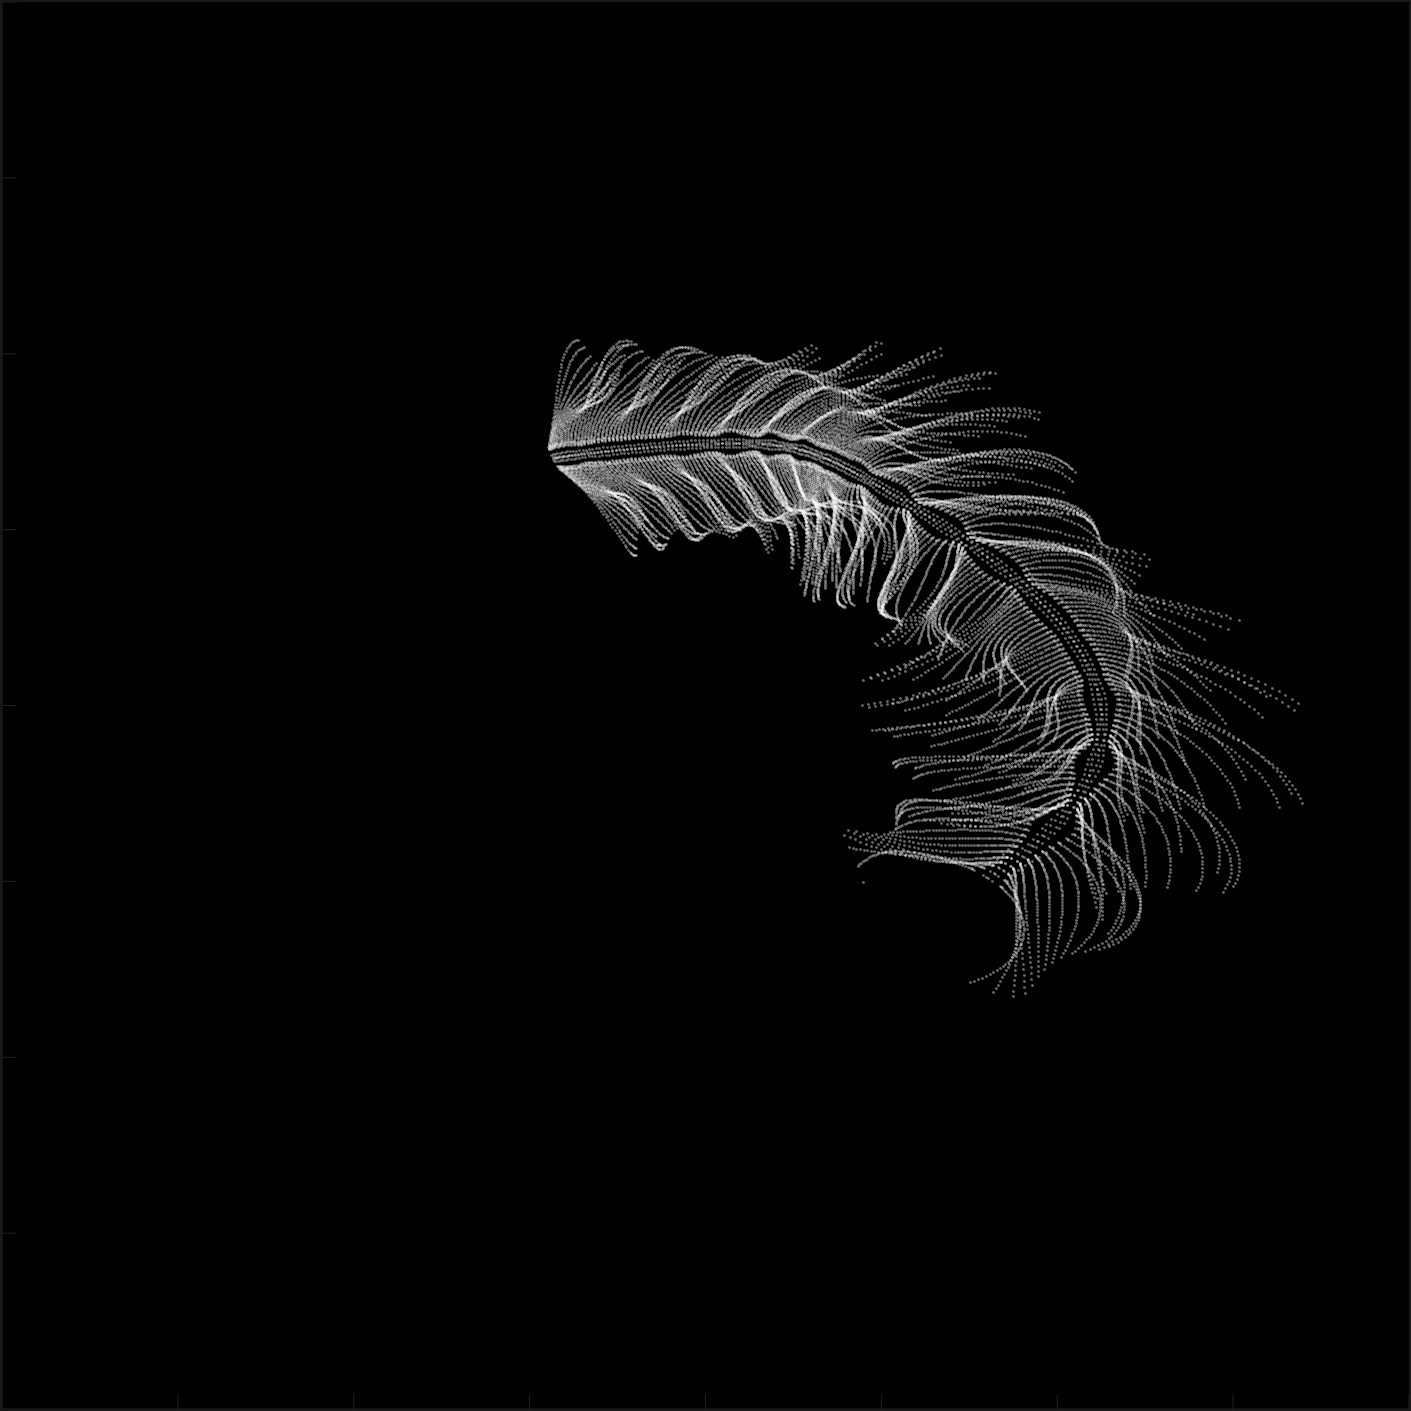

%% Animation 1 – Mod Grid Flow
% A modular grid deformed by sine/cosine waves, creating a fluid‑like motion.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
ax = axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 2, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

% Precompute grid indices
i = 0:2e4;
x = mod(i,100);
y = floor(i./100);
k = x./4 - 12.5;
e = y./9 + 5;
o = vecnorm([k; e])./9;      % radial distance factor

t = 0;
dt = pi/90;

while ishandle(fig)
    t = t + dt;
    q = x + 99 + tan(1./k) + o.*k.*(cos(e.*9)./4 + cos(y./2)).*sin(o.*4 - t);
    c = o.*e./30 - t./8;
    
    X = (q.*0.7.*sin(c)) + 9.*cos(y./19 + t) + 200;
    Y = 200 + (q./2.*cos(c));
    
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(1/60);
end

**Animation 2 – Wave Curve (Code section)**

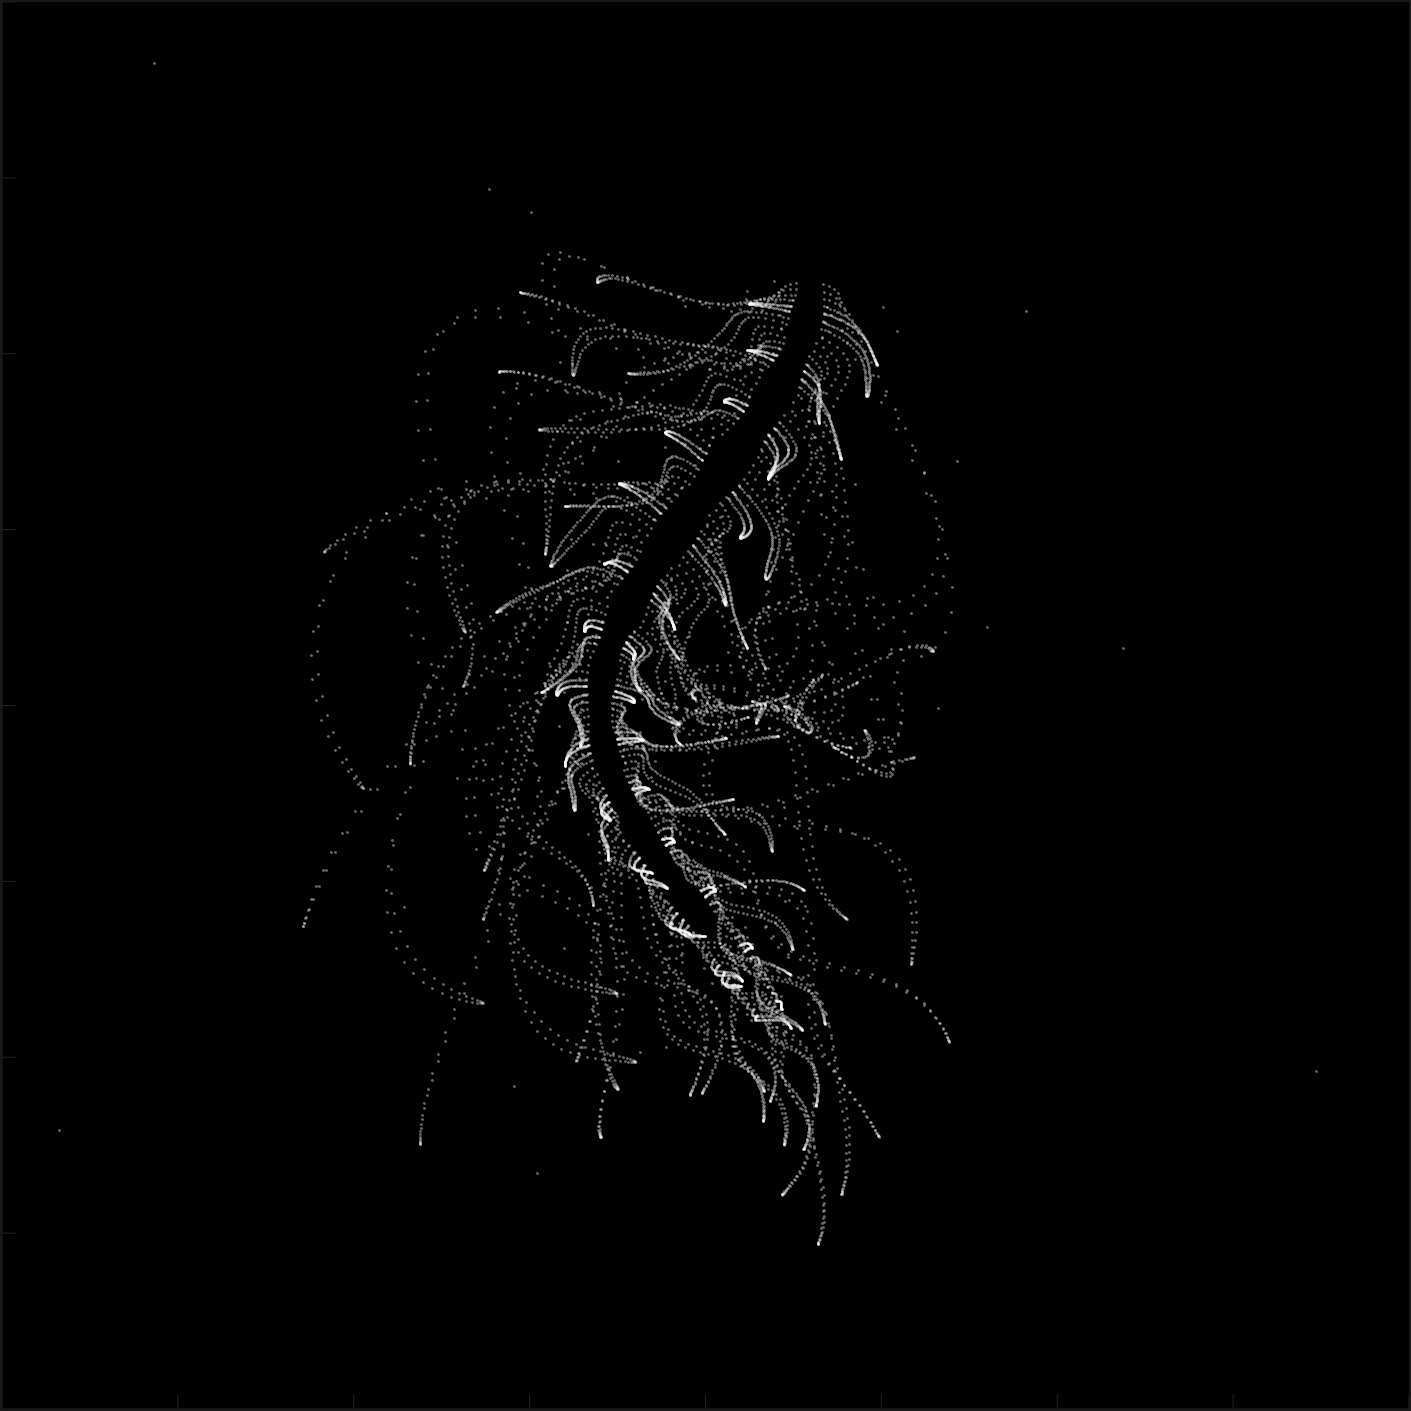

%% Animation 2 – Wave Curve
% An undulating curve with dynamic radial offset.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 2, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

i = 0:1e4;
x = i;
y = i./235;
e = y./8 - 13;

t = 0;
dt = pi/240;

while ishandle(fig)
    t = t + dt;
    k = (4 + sin(y.*2 - t).*3) .* cos(x./29);
    d = vecnorm([k; e]);
    q = 3.*sin(k.*2) + 0.3./k + sin(y./25).*k.*(9 + 4.*sin(e.*9 - d.*3 + t.*2));
    
    X = q + 30.*cos(d - t) + 200;
    Y = 620 - q.*sin(d - t) - d.*39;
    
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(1/60);
end

**Animation 3 – Rotating Rings (Code section)**

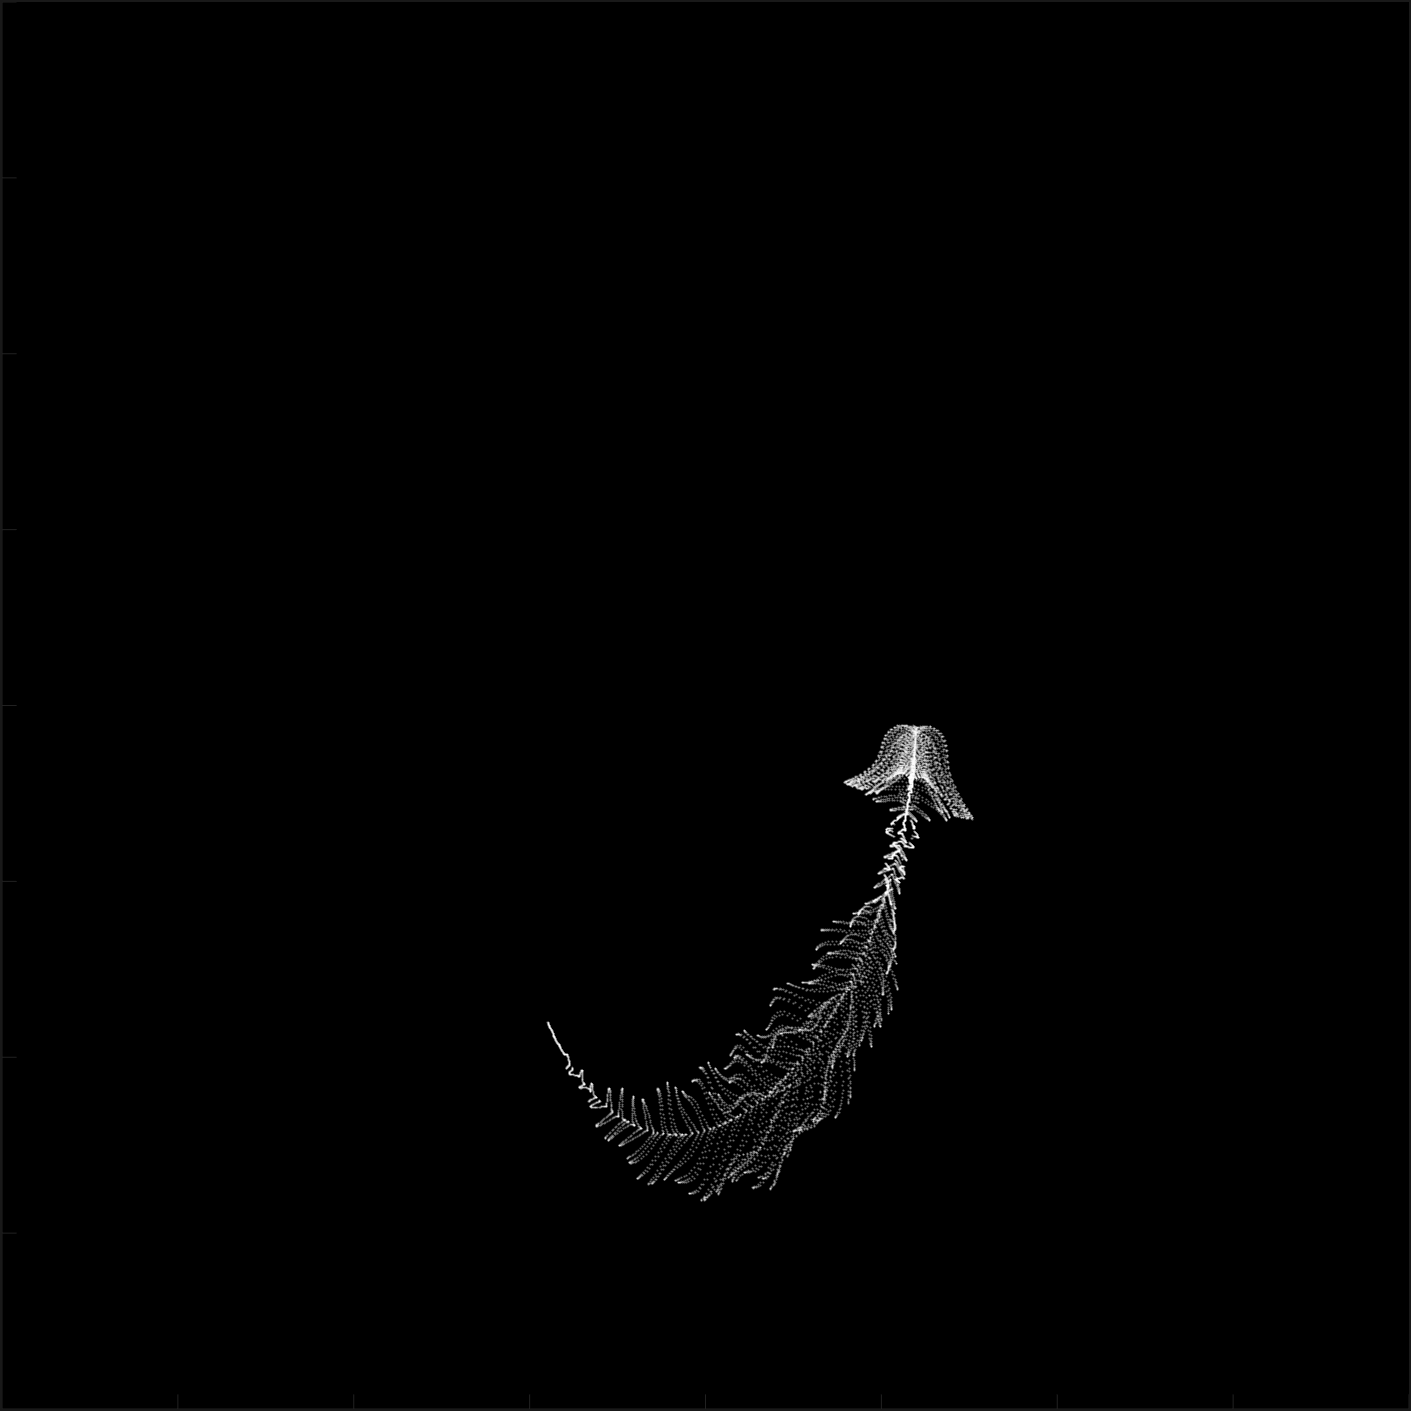

%% Animation 3 – Rotating Rings
% Multiple rings rotating with inner harmonic motion.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 1, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

i = 0:1e4;
x = mod(i,200);
y = i./43;
k = 5.*cos(x./14).*cos(y./30);
e = y./8 - 13;
d = (k.^2 + e.^2)./59 + 4;
a = atan2(k,e);

t = 0;
dt = pi/20;

while ishandle(fig)
    t = t + dt;
    q = 60 - 3.*sin(a.*e) + k.*(3 + 4./d.*sin(d.^2 - t.*2));
    c = d./2 + e./99 - t./18;
    
    X = q.*sin(c) + 200;
    Y = (q + d.*9).*cos(c) + 200;
    
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(0.01);
end

**Animation 4 – Color Swirl (Code section)**

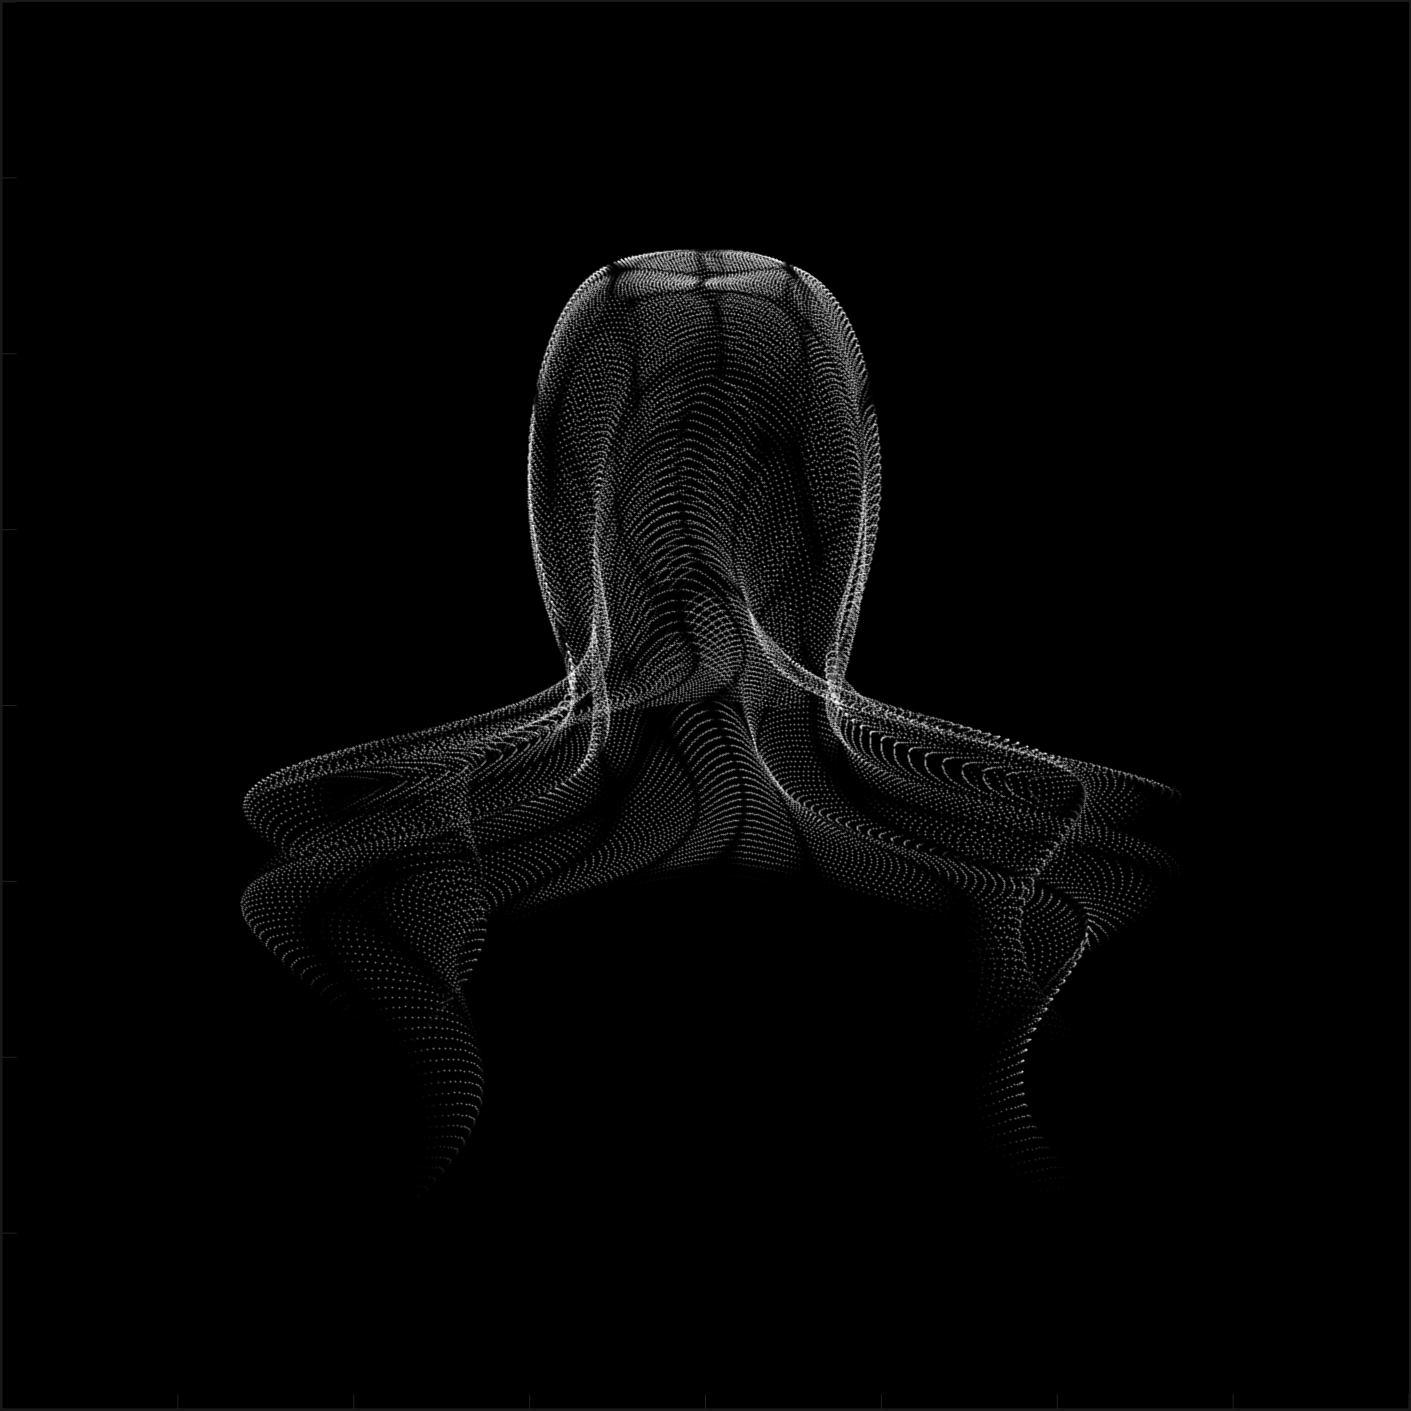

%% Animation 4 – Color Swirl
% A colour‑changing swirl where dot intensity varies with time.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 1, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

i = 0:4e4;
x = mod(i,200);
y = i./200;
k = x./8 - 12.5;
e = y./8 - 12.5;
o = (k.^2 + e.^2)./169;
d = 0.5 + 5.*cos(o);

t = 0;
dt = pi/120;

while ishandle(fig)
    t = t + dt;
    X = x + d.*k.*sin(d.*2 + o + t) + e.*cos(e + t) + 100;
    Y = y./4 - o.*135 + d.*6.*cos(d.*3 + o.*9 + t) + 275;
    
    intensity = (d .* sin(k) .* sin(t.*4 + e)).^2;
    scatterObj.CData = intensity(:) .* [1,1,1];   % grayscale brightness
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(1/60);
end

**Animation 5 – Spiral Dance (Code section)**

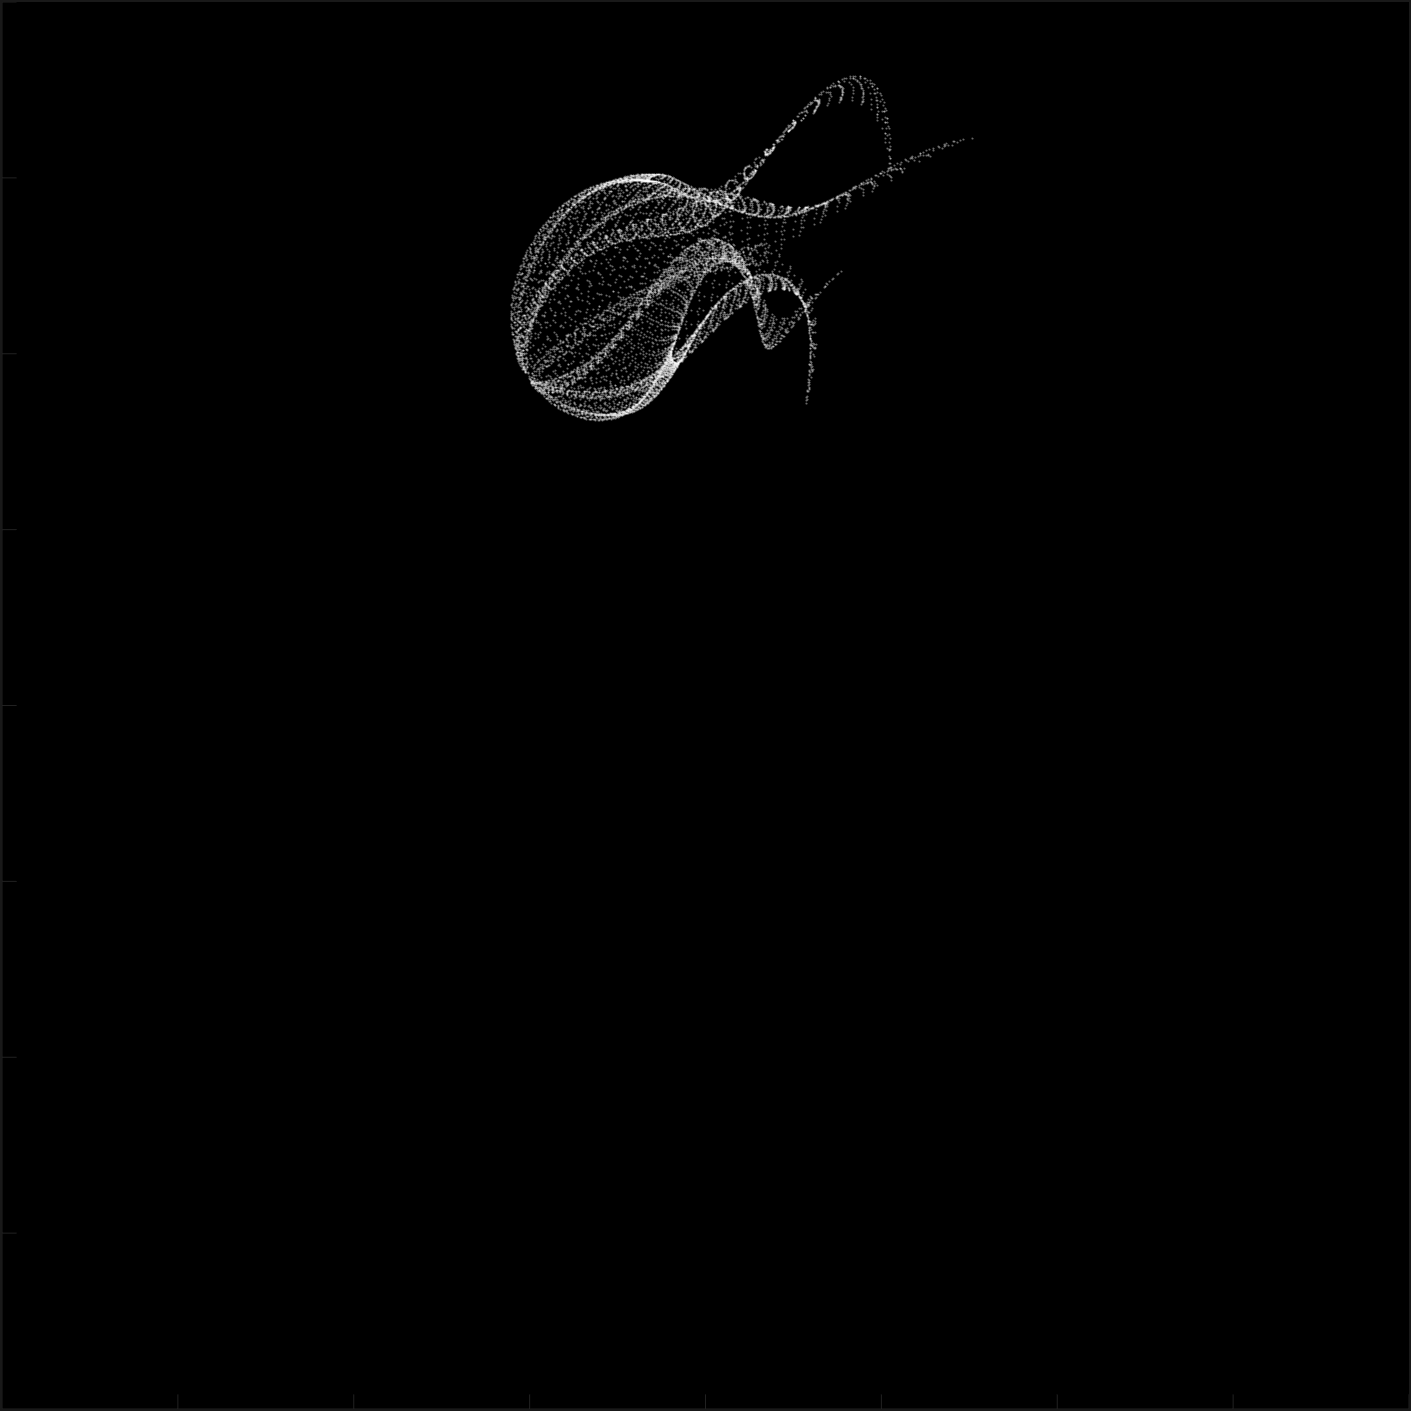

%% Animation 5 – Spiral Dance
% Spiralling dots with dynamically changing radius.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 1, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

i = 0:1e4;
x = mod(i,200);
y = i./55;
k = 9.*cos(x./8);
e = y./8 - 12.5;

t = 0;
dt = pi/120;

while ishandle(fig)
    t = t + dt;
    d = (k.^2 + e.^2)./99 + sin(t)./6 + 0.5;
    q = 99 - e.*sin(atan2(k,e).*7)./d + k.*(3 + cos(d.^2 - t).*2);
    c = d./2 + e./69 - t./16;
    
    X = q.*sin(c) + 200;
    Y = (q + 19.*d).*cos(c) + 200;
    
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(1/60);
end

**Animation 6 – Bitxor Pattern (Code section)**

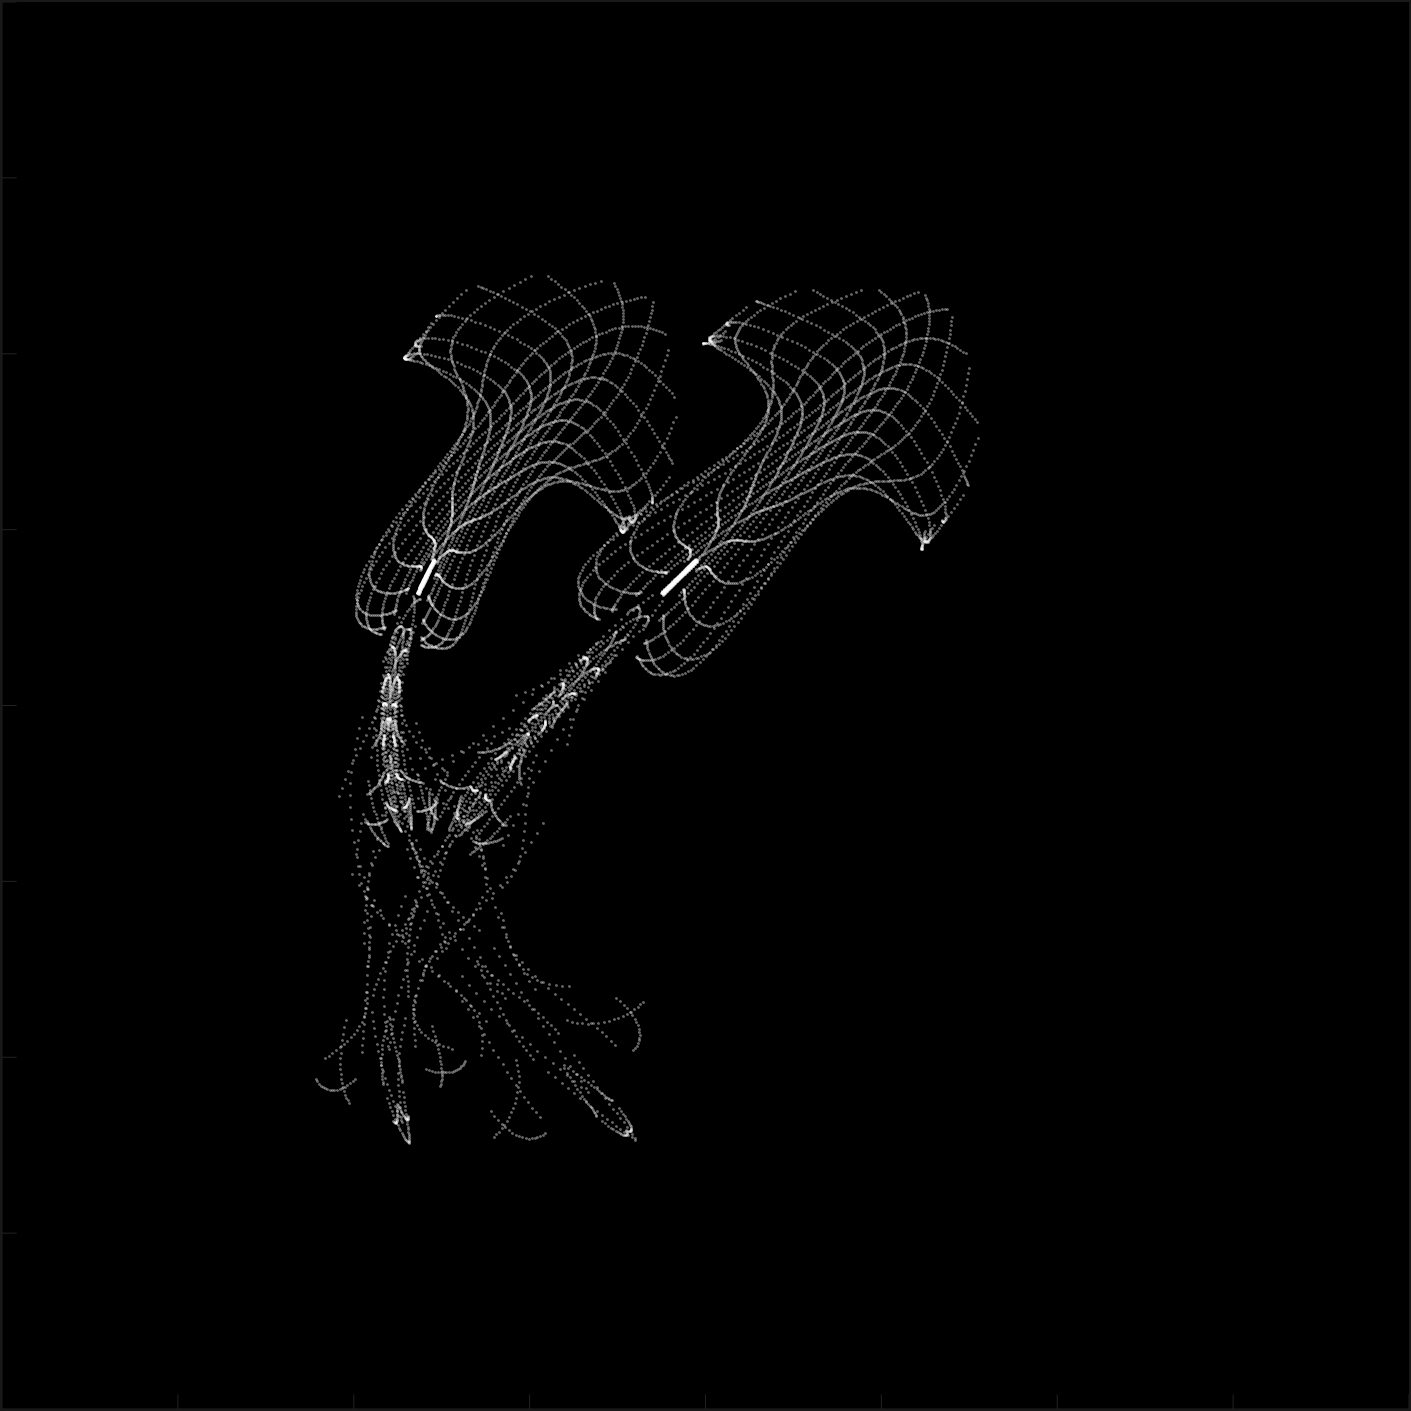

%% Animation 6 – Bitxor Pattern
% Uses bitwise XOR to create two distinct regions in the field.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 2, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

i = 1:1e4;
y = i./790;
k = y;
idx = y < 5;
k(idx) = 6 + sin(bitxor(floor(y(idx)),1)).*6;
k(~idx) = 4 + cos(y(~idx));

t = 0;
dt = pi/90;

while ishandle(fig)
    t = t + dt;
    d = sqrt((k.*cos(i + t./4)).^2 + (y/3 - 13).^2);
    q = y.*k.*cos(i + t./4)./5 .* (2 + sin(d.*2 + y - t.*4));
    c = d./3 - t./2 + mod(i,2);
    
    X = q + 90.*cos(c) + 200;
    Y = 400 - (q.*sin(c) + d.*29 - 170);
    
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(0.01);
end

**Animation 7 – Variable Density (Code section)**

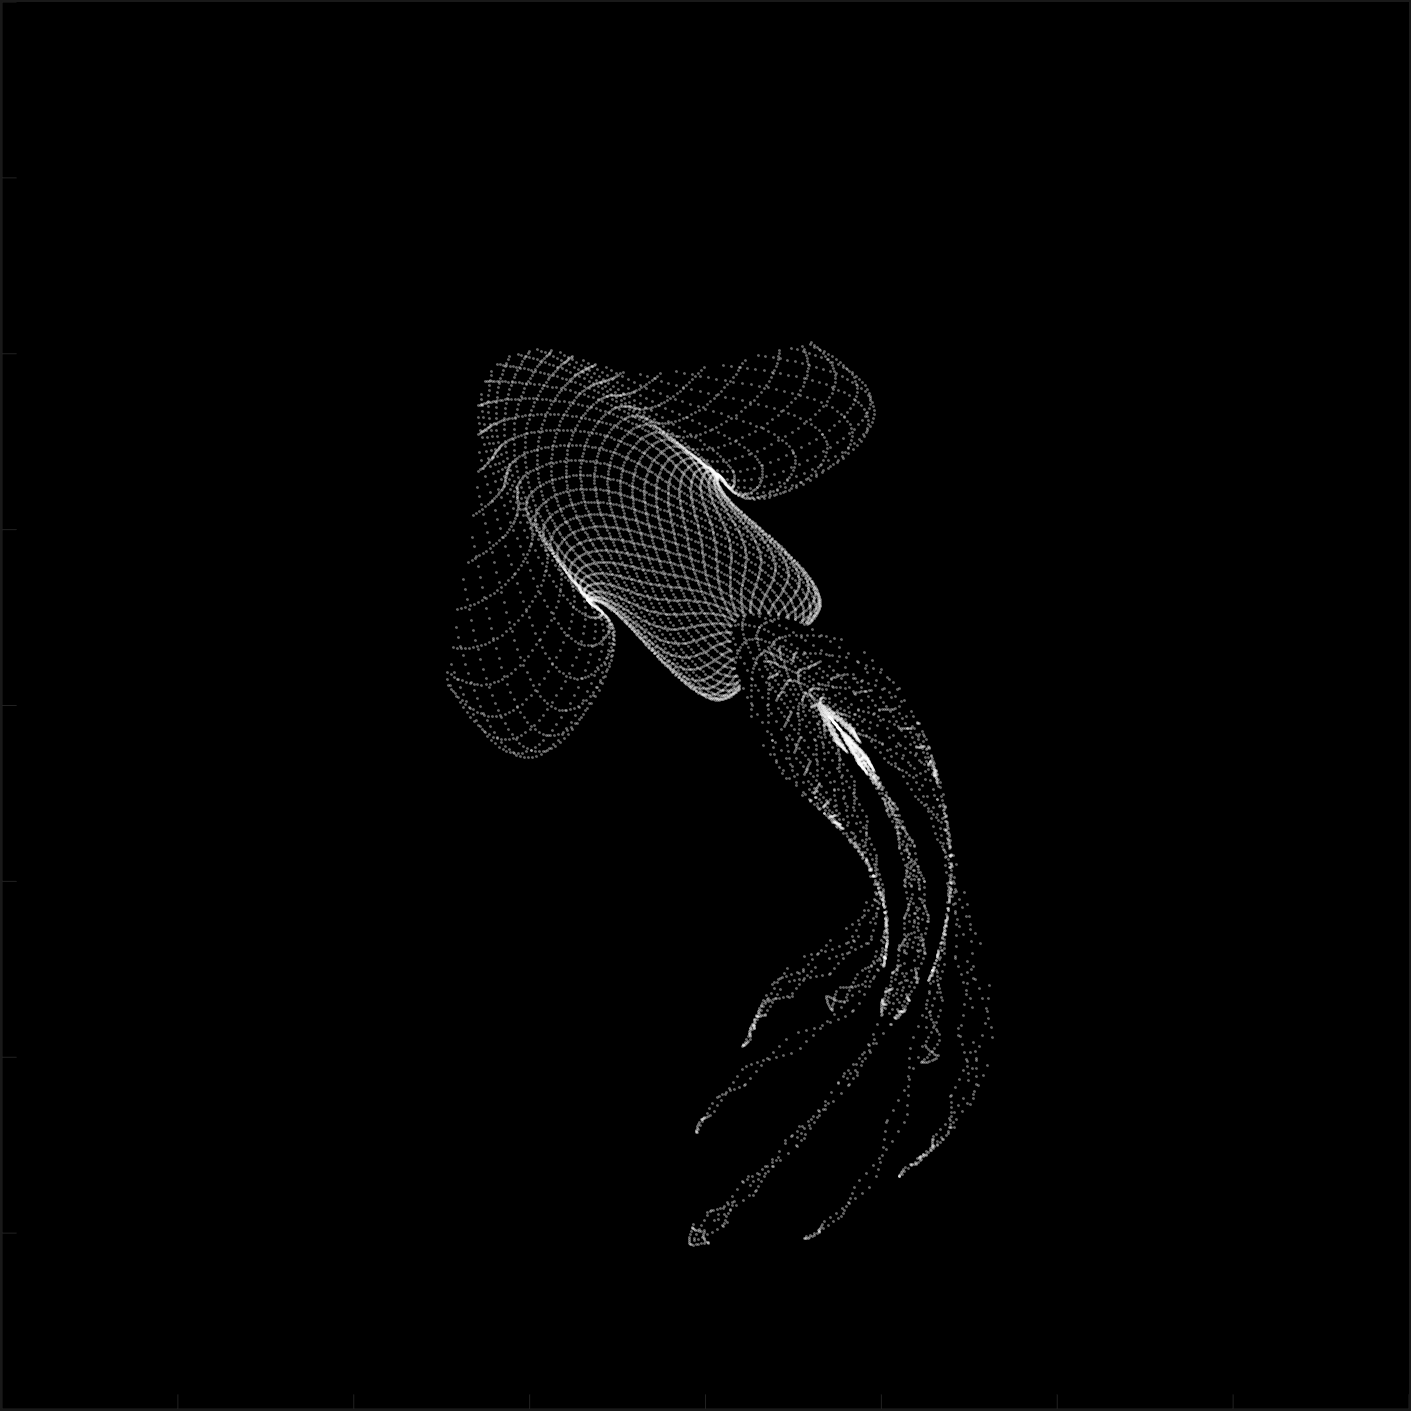

%% Animation 7 – Variable Density
% Density modulation based on a conditional index transformation.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

scatterObj = scatter([],[], 2, 'filled','o','w', ...
    'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.4);

i = 1:1e4;
y = i./345;
x = y;
idx = y < 11;
x(idx) = 6 + sin(bitxor(floor(x(idx)),8))*6;
x(~idx) = x(~idx)./5 + cos(x(~idx)./2);
e = y./7 - 13;

t = 0;
dt = pi/120;

while ishandle(fig)
    t = t + dt;
    k = x.*cos(i - t./4);
    d = sqrt(k.^2 + e.^2) + sin(e./4 + t)./2;
    q = y.*k./d .* (3 + sin(d.*2 + y./2 - t.*4));
    c = d./2 + 1 - t./2;
    
    X = q + 60.*cos(c) + 200;
    Y = 400 - (q.*sin(c) + d.*29 - 170);
    
    scatterObj.XData = X;
    scatterObj.YData = Y;
    drawnow;
    pause(0.005);
end

** Animation 8 – Hexagon Swarm (Code section)**

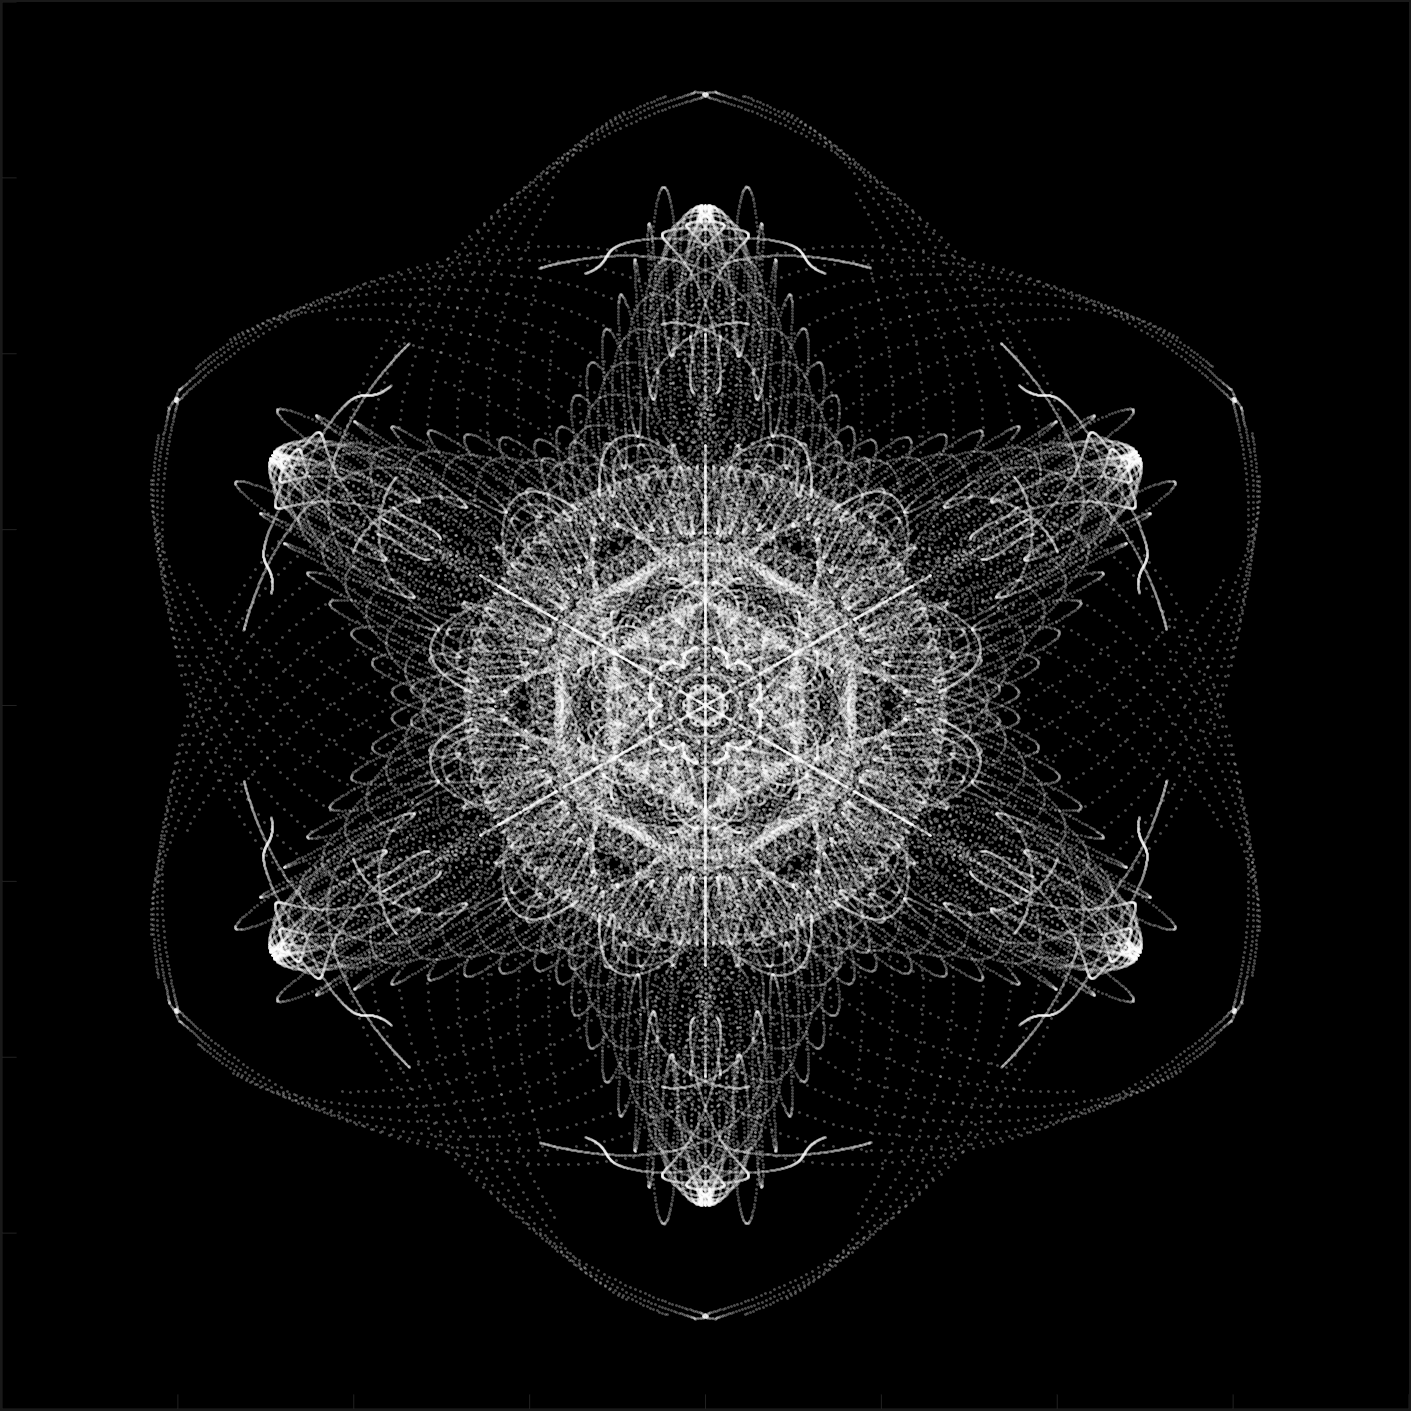

%% Animation 8 – Hexagon Swarm
% Six rotating swarms arranged in a hexagonal pattern.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
ax = axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

nSwarms = 6;
swarms = cell(1,nSwarms);
for j = 1:nSwarms
    swarms{j} = scatter([],[], 2, 'filled','o','w', ...
        'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.3);
end

i = 1:2e4;
k = mod(i,25) - 12;
e = i./800;
center = 200;
theta = pi/3;
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];

t = 0;
dt = pi/240;

while ishandle(fig)
    t = t + dt;
    d = 7.*cos(sqrt(k.^2 + e.^2)./3 + t./2);
    XY = [k.*4 + d.*k.*sin(d + e./9 + t);
          e.*2 - d.*9 - d.*9.*cos(d + t)];
    
    for j = 1:nSwarms
        XY = R * XY;
        swarms{j}.XData = XY(1,:) + center;
        swarms{j}.YData = XY(2,:) + center;
    end
    drawnow;
    pause(1/60);
end

**Animation 9 – Multi‑Layer Rotation (Code section)**

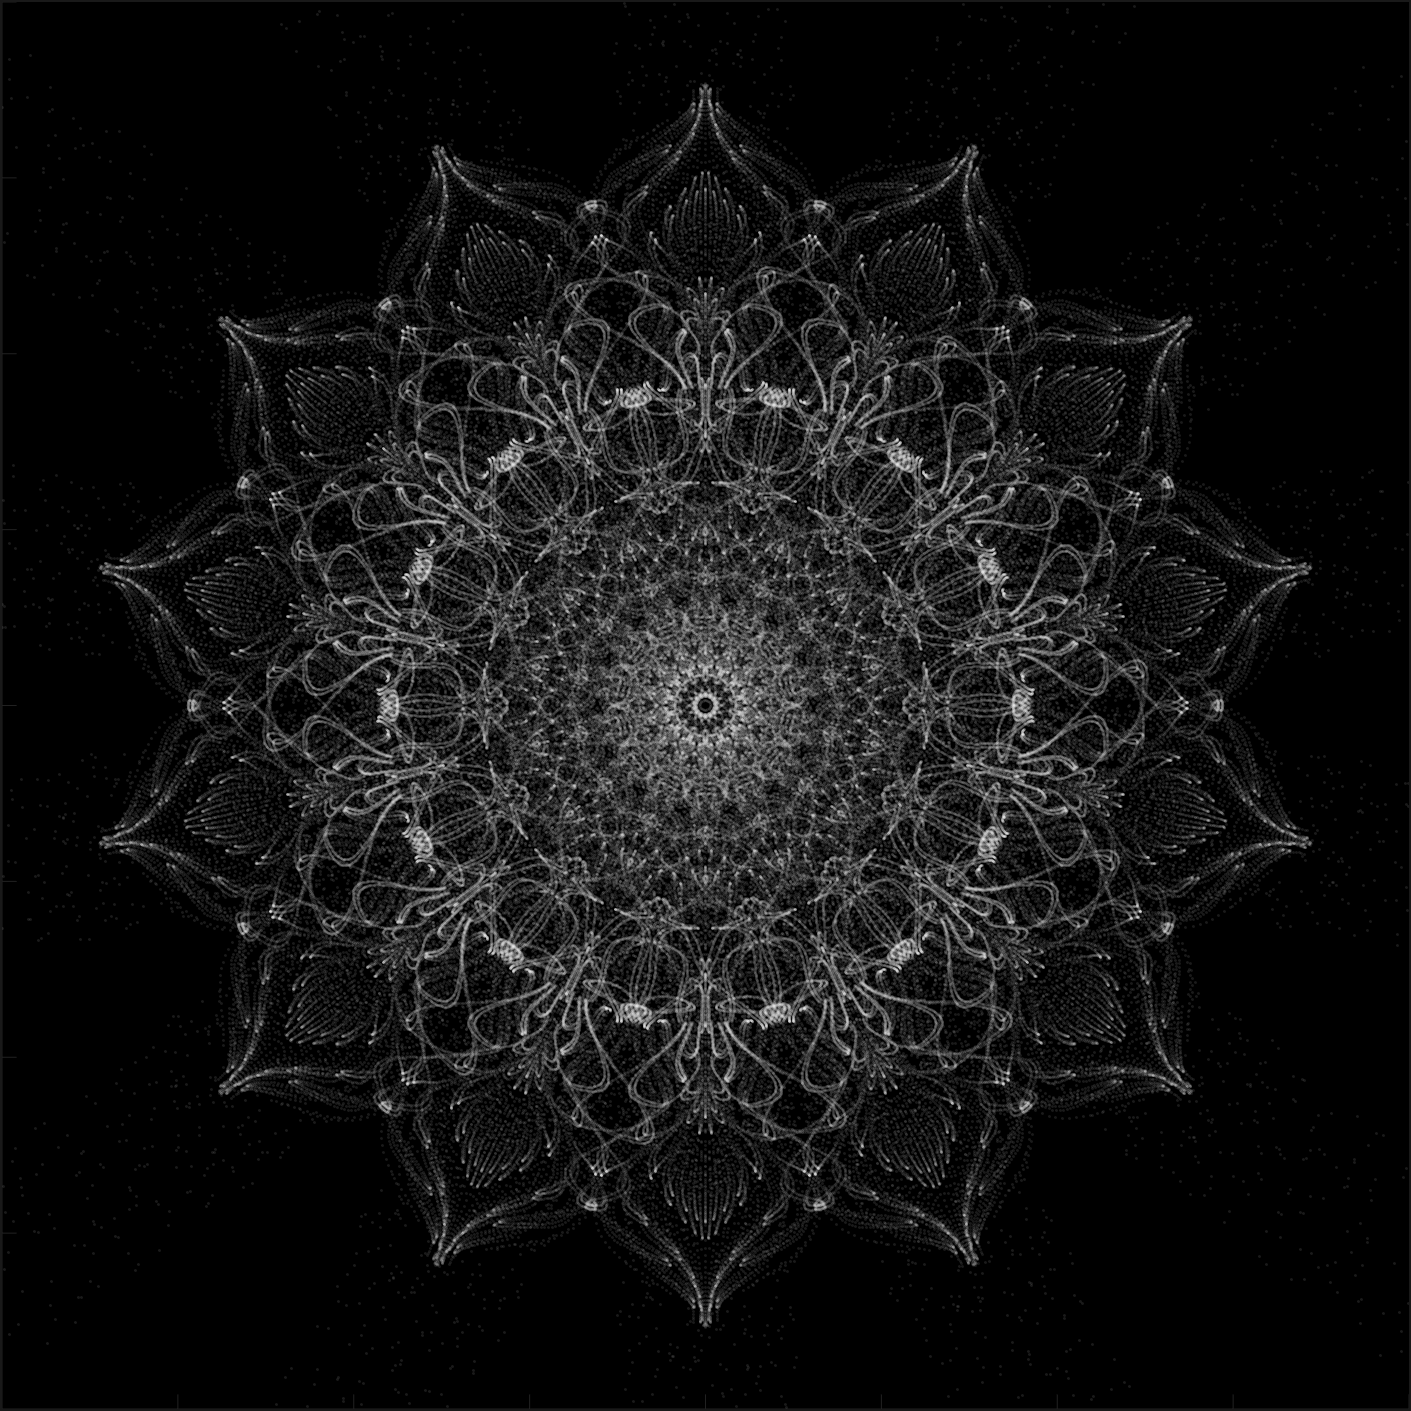

%% Animation 9 – Multi‑Layer Rotation
% Fourteen layers rotating together, each with a different offset.

clear; close all; clc;

fig = figure('Position',[300,50,900,900], 'Color','k');
ax = axes(fig, 'NextPlot','add', 'Position',[0,0,1,1], 'Color','k');
axis([0,400,0,400]); axis off;

nLayers = 14;
layers = cell(1,nLayers);
for j = 1:nLayers
    layers{j} = scatter([],[], 2, 'filled','o','w', ...
        'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.1);
end

i = 1:2e4;
k = mod(i,50) - 25;
e = i./1100;
center = 200;
theta = pi/7;
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];

t = 0;
dt = pi/240;

while ishandle(fig)
    t = t + dt;
    d = 5.*cos(sqrt(k.^2 + e.^2) - t + mod(i,2));
    XY = [k + k.*d./6.*sin(d + e./3 + t);
          90 + e.*d - e./d.*2.*cos(d + t)];
    
    for j = 1:nLayers
        XY = R * XY;
        layers{j}.XData = XY(1,:) + center;
        layers{j}.YData = XY(2,:) + center;
    end
    drawnow;
    pause(1/60);
end